# High Voltage Battery - Test Case

## Constant inputs

Use this to check that simulation runs ok.

mdl = "BatteryHV_harness_model";
load_system(mdl)

% Load model parameters.
BatteryHV_harness_setup

% Select battery model.
% BatteryHV_useRefsub_Basic
BatteryHV_useRefsub_SystemLevelTableBased

Model: BatteryHV_harness_model
Setting up referenced subsystem: BatteryHV_refsub_SystemLevelTableBased



% Setup simulation case.
BatteryHV_selectSimulationCase_Constant

Setting up simulation...
Simulation case: Constant inputs
Setting simulation stop time to 1000 sec.
Setting block parameters for input blocks...
Setting initial conditions...
initial.hvBattery_SOC_pct = 50
initial.hvBattery_Charge_Ahr = 69.4444
initial.hvBattery_Temperature_K = 293.15


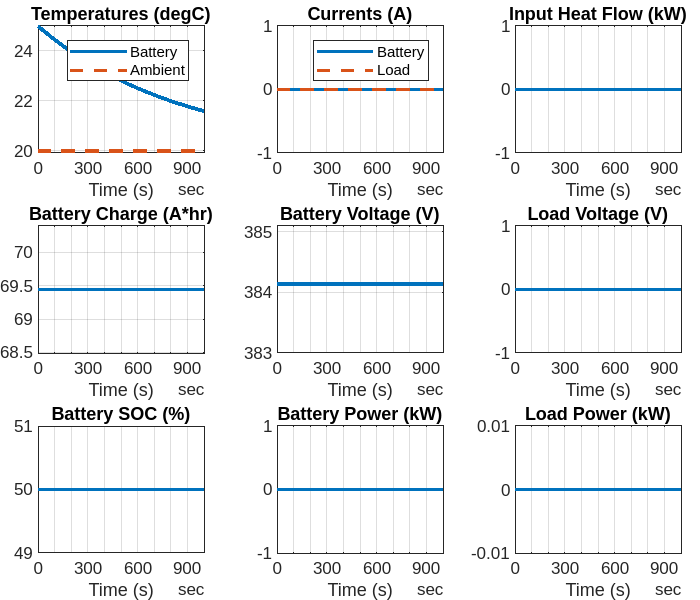


% ambient.temp_K =  273.15 + inpData.Options.InitialTemperature_degC;
% initial.hvBattery_Temperature_K = ambient.temp_K;

% Run simulation.
simOut = sim(mdl);

% Collect logged signals and visualize.
% The basic version of the battery block does not simulate battery temperature.
logged_signals = extractTimetable(simOut.logsout);
BatteryHV_plotResults(logged_signals);

*Copyright 2020-2022 The Mathworks, Inc.*